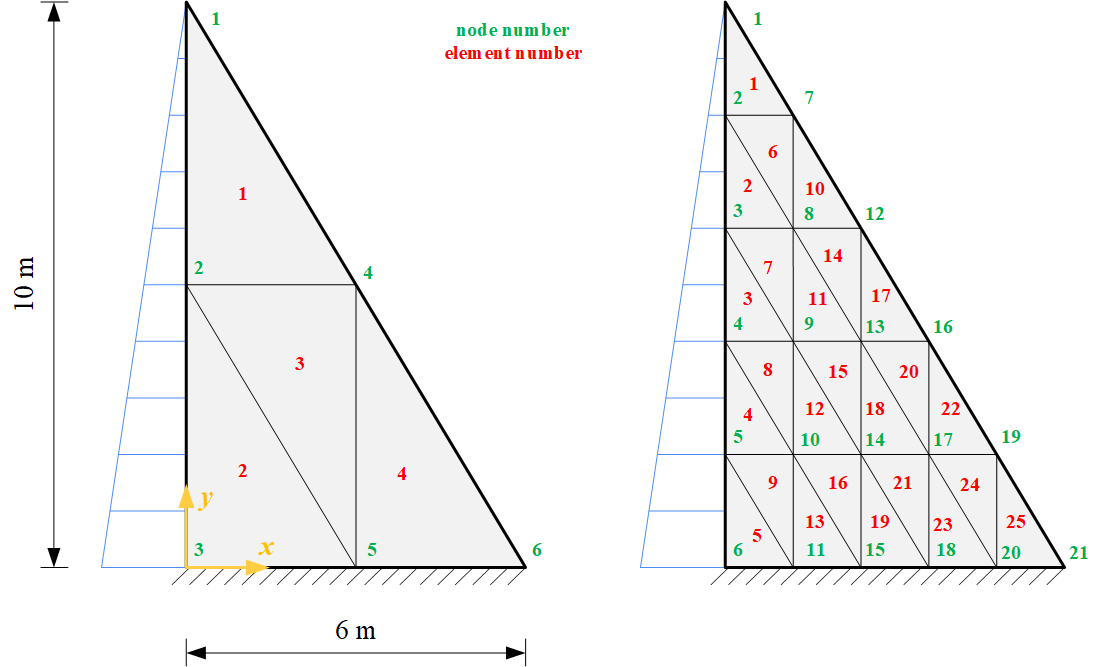

clear;clc
load('example_4elem.mat')
E = 3e10;
mu = 0.3;
t = 1;
type = 2;
[K,~] = getTriangleK(node,elem,E,mu,t,type);
q = [1 0 0
    2 5e4*t 0
    3 10e4*t 0];
F = distriQs(node,q);
cons = [5 0; 6 0; 10 0; 12 0];
d1 = solveTriangle(K,F,cons);

load('example_25elem.mat')
E = 3e10;
mu = 0.3;
t = 1;
type = 2;
[K,~] = getTriangleK(node,elem,E,mu,t,type);
q = [1 0 0
    2 5e4*t 0
    3 10e4*t 0];
F = distriQs(node,q);
cons = [11 0
        12 0
        22 0
        30 0
        36 0
        40 0
        42 0];
d2 = solveTriangle(K,F,cons);